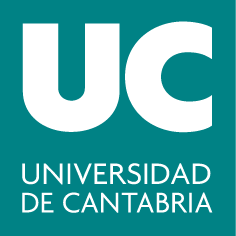

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 9: Resolución numérica de ecuaciones diferenciales de primer orden**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos		

- Utilizar el métodos de resolución numérica para aproximar la solución de un problema de valor inicial en un conjunto de puntos dado. Evaluar el error cometido en la aproximación.	

- Comparar los resultados alcanzados cuando se utilizan distintos métodos de resolución numérica.

### Resumen teórico

#### Método de Euler básico

El método de las tangentes o *método de Euler* básico nos da una primera aproximación de los valores que toma la solución de un problema de valor inicial, sobre un conjunto de puntos dados:


$$y'=f(x,y)$$



$$y(x_0)=y_0$$


En cada paso se aproxima el valor de la función en un punto, mediante la recta tangente estimada en el punto anterior. Las fórmulas recursivas, que determinan los vértices de la línea poligonal que aproxima la solución del problema de valor inicial, son:

$x_{n+1}=x_{n}+h$        $y_{n+1}=y_{n}+hf(x_{n},y_{n})$        con $n=0,1,2,3,...$

#### Método de Euler mejorado

En este método, en vez de aproximar la solución en cada punto mediante la recta tangente estimada en el punto anterior, se aproxima con una recta cuya pendiente $m$ es la media de las pendientes de las rectas tangentes estimadas en el propio punto y en el anterior:

$m=\frac{m_{n}+m_{n+1}}{2}$   donde $m_{n}=f(x_{n}, y_{n})$, $m_{n+1}=f(x_{n+1},yest_{n+1})$

Las fórmulas recursivas para determinar los vértices de la poligonal que aproxima la solución del problema de valor inicial, son:

$x_{n+1}=x_{n}+h$       $yest_{n+1}=y_{n}+hf(x_{n},y_{n})$      $y_{n+1}=y_{n}+\frac{h}{2}\Big[f(x_{n},y_{n})+f(x_{n+1},yest_{n+1})\Big]$        con $n=0,1,2,3,...$

#### Método de Runge-Kutta de orden 4

$\displaystyle y_{n+1}= y_{n}+\frac{h}{6}\Big[K_{1}+2K_{2}+2K_{3}+K_{4}\Big] \\
x_{n+1}=x_{n}+h    $     donde     $
K_{1}= f(x_{n},y_{n}) \\ 	K_{2}=f(x_{n} +\frac{h}{2},y_{n}+\frac{h}{2}K_{1}) \\ 	K_{3}= f(x_{n}+\frac{h}{2},y_{n}+\frac{h}{2}K_{2}) \\ 	K_{4}= f(x_{n}+h,y_{n}+hK_{3}) 
$

Mientras que el método de Euler básico tiene una velocidad de convergencia $p=1$, esto significa que para conseguir un error menor que $10^{-2}$ se necesitarán normalmente más de $100$ pasos, el método de Euler mejorado converge con velocidad $p=2$ y el método de Runge-Kutta de orden cuatro con $p=4$.

### Comandos útiles

#### Comando para resolver ecuaciones diferenciales de forma exacta

- `syms y(x)`: crea la variable simbólica `y` que depende de `x`.

- `diff(var, n)`:  Para denotar la derivada de la variable simbólica `var` de orden `n`.

- `dsolve('eq', 'cond')`: Para resolver ecuaciones diferenciales de forma simbólica. 

Ejemplos:

syms y(x)
solEDO=dsolve(diff(y,x) ==-3*x) 

Si se añade una condición inicial se obtiene la solución particular al problema de valor inicial:

solPVI=dsolve(diff(y,x) ==-3*x, y(0)==1) 

#### Comandos para trabajar con funciones

- `@`: Sirve para crear un identificador de función. Ejemplo:

f=@(x,y) 2*x+y
f(2,1)

- `str2func('S')`: convierte en una función la cadena de caracteres en `'S'`. Ejemplo:

f= str2func("@(x,y) 2*x+y")
f(2,1)

- `inline('expresion')`: construye una función en línea a partir de la expresión indicada. 

- `vectorize(f):` vectoriza la fórmula de la función que aparece en el argumento de entrada. A menudo usaremos estos dos funciones juntas. Ejemplo:

syms x
fun_eval=vectorize(inline(2*x));
fun_eval([2,4,6])

#### Comandos para crear una función

- `function [out1, out2, ...] = funname(in1, in2, ...)` Crea una función de nombre `funname`, con unos parámetros de entrada `(in1,in2,…) `y unas variables de salida `(out1, out2,…)`. Debe terminar con el comando `end`. Se debe guardar la función en un fichero llamado `funname.m. `

###  Ejercicio resuelto

**1. [Ejercicio 4.25 del tema] Aproximación numérica de las soluciones de una EDO de primer orden**

Se considera el problema de valor inicial:  $y'=\frac{-x}{y}$,   $y(0)=4$

en los puntos $x= 0.1, 0.2, 0.3, 0.4, 0.5$, con valor de paso $h=0.1$.

a) Utiliza las fórmulas del método de Euler básico para calcular la solución aproximada de ese problema de valor inicial en los puntos dados. 

b) Utiliza las fórmulas del método de Euler mejorado para calcular la solución aproximada de ese problema de valor inicial en los puntos dados. 

c) Utiliza el método de Runge-Kutta para calcular la solución aproximada de ese problema de valor inicial en los puntos dados. 

d) Calcula la solución exacta y los errores cometidos en cada caso.

e) Representa gráficamente la solución exacta y las aproximaciones y comenta el resultado.

En primer lugar, definimos nuestra ecuación diferencial como función en línea, ya que el valor de $y'=f(x,y)$ evaluada en un punto da la pendiente de la recta tangente a la solución en ese punto, que se usará en los tres métodos.

f=@(x,y) -x/y; % Evaluando la EDO conoceremos la pendiente en un punto

Definimos los puntos de estudio, el valor de paso y el número de iteraciones. Llamaremos `xn` a las coordenadas en el eje OX de los cinco puntos de estudio (iguales para todos los métodos de aproximación). `yn_ebasico`, `yn_emejorado`, `yn_rk` serán la coordenadas en el eje OY de los valores aproximados por los métodos de Euler básico, de Euler mejorado y Runge-Kutta, respectivamente.

x0=0; y0=4; xfinal=0.5; h=0.1; % Definimos los puntos de estudio
nmax= (xfinal-x0)/h; % número máximo de iteraciones
xn=x0:h:xfinal;% Coordenada x de los puntos de estudio (son las mismas para los tres métodos)

a) Utiliza las fórmulas del método de Euler básico para calcular la solución aproximada de ese problema de valor inicial en los puntos dados. 

Las fórmulas del método de Euler básico son:

$x_{n+1}=x_{n}+h$      $y_{n+1}=y_{n}+hf(x_{n},y_{n})$    con $n=0,1,2,3,...$

En primer lugar, vamos a plantear la resolución mediante el método de Euler paso a paso:

La condición inicial es $x_{0}=0$, $y_{0}=4$, por lo tanto las coordenadas del primer punto estimado serían: 


$$x_{1}=x_{0}+h=0+0.1=0.1$$
     
$$y_{1}=y_{0}+hf(x_{0},y_{0})=4-0.1\frac{0}{4}=4$$


Partiendo de $(x_{1}, y_{1})$ se obtienen las coordenadas del siguiente: 


$$x_{2}=x_{1}+h=0.1+0.1=0.2$$
        
$$y_{2}=y_{1}+hf(x_{1},y_{1})=4-0.1\frac{0.1}{4}=3.9975$$


Partiendo de $(x_{2},y_{2})$ se obtienen las coordenadas del siguiente: 


$$x_{3}=x_{2}+h=0.2+0.1=0.3$$
        
$$y_{3}=y_{2}+hf(x_{2},y_{2})=3.9975-0.1\frac{0.2}{3.9975}=3.9925$$


Partiendo de $(x_{3},y_{3})$ se obtienen las coordenadas del siguiente: 


$$x_{4}=x_{3}+h=0.3+0.1=0.4$$
        
$$y_{4}=y_{3}+hf(x_3, y_3)=3.9925-0.1\frac{0.3}{3.9925}=3.9850$$


Finalmente, partiendo de $(x_{4},y_{4})$ se obtienen las del último punto: 


$$x_{5}=x_{4}+h=0.4+0.1=0.5$$
     
$$y_{5}=y_{4}+hf(x_{4},y_{4})=3.9850-0.1\frac{0.4}{3.9850}=3.9749$$


Se resolvería con Matlab de la siguiente manera:

yn_ebasico(1)=y0; % Coordenada y del punto inicial por donde pasa la solución
for i=1:nmax
    yn_ebasico(i+1)=yn_ebasico(i)+h*f(xn(i),yn_ebasico(i)); % Coordenadas y_n+1
end

b) Utiliza las fórmulas del método de Euler mejorado para calcular la solución aproximada de ese problema de valor inicial en los puntos dados. 

Las fórmulas recursivas en el caso del método de Euler mejorado son:

$x_{n+1}=x_{n}+h$      $yest_{n+1}=y_{n}+hf(x_{n},y_{n})$     $y_{n+1}=y_{n}+\frac{h}{2}\Big[f(x_{n},y_{n})+f(x_{n+1},yest_{n+1})\Big]$       con $n=0,1,2,3,...$

La condición inicial es $x_{0}=0$, $y_{0}=4$, por lo tanto las coordenadas del primer punto estimado serían: 


$$x_{1}=x_{0}+h=0+0.1=0.1$$
        
$$yest_{1}=y_{0}+hf(x_{0},y_{0})=4-0.1\frac{0}{4}=4$$
        
$$y_{1}=y_{0}+\frac{h}{2}[f(x_{0},y_{0})+f(x_{1}, yest_{1})]=4+\frac{0.1}{2}\Big[-\frac{0}{4}-\frac{0.1}{4}\Big]=3.99875$$


El siguiente punto sería:


$$x_{2}=x_{1}+h=0.1+0.1=0.2$$
        
$$yest_{2}=y_{1}+hf(x_{1},y_{1})=3.9987-0.1\frac{0.1}{3.9987}=3.9962$$
        
$$y_{2}=y_{1}+\frac{h}{2}[f(x_{1},y_{1})+f(x_{2}, yest_{2})]=3.9987+\frac{0.1}{2}\Big[-\frac{0.1}{3.9987}-\frac{0.2}{3.9962}\Big]=3.9949973$$


Y así sucesivamente. En Matlab:

yn_emejorado(1)=y0; % Coordenada y del punto inicial por donde pasa la solución
for i=1:nmax
    yest=yn_emejorado(i)+h*f(xn(i),yn_emejorado(i)); 
    yn_emejorado(i+1)=yn_emejorado(i)+ h*(f(xn(i),yn_emejorado(i))+...
    f(xn(i+1),yest))/2; % Coordenadas y_n+1
end

c) Utiliza el método de Runge-Kutta para calcular la solución aproximada de ese problema de valor inicial en los puntos dados. 

yn_rk(1)=y0; % Coordenada y del punto inicial por donde pasa la solución
for i=1:nmax
    k1= f(xn(i),yn_rk(i));
    k2= f(xn(i)+h/2, yn_rk(i)+h*k1/2);
    k3= f(xn(i)+h/2, yn_rk(i)+h*k2/2);
    k4= f(xn(i+1), yn_rk(i)+h*k3);
    yn_rk(i+1)=yn_rk(i)+h*(k1+2*k2+2*k3+k4)/6; % Coordenadas y_n+1
end

Existe la función ode45 que calcula la solución aproximada por el método de Runge-Kutta de orden 4 de forma sencilla:

yn_rk2= ode45(f,xn,y0) % yn_rk2.y contiene la aproximación

d) Calcula la solución exacta y los errores cometidos en cada caso.

syms y(x) 
yexacta=dsolve(diff(y,x) ==-x/y,y(x0)==y0) % Solución exacta al pvi 

Hacemos esa función evaluable para hallar las ordenadas asociadas a los $x_{n}$. Hay (al menos) dos maneras posibles:

%yexacta_eval=@(x) eval(vectorize(yexacta));
yexacta_eval=vectorize(inline(yexacta));
valor_exacto=yexacta_eval(xn) %Valores exactos de la solución en los puntos x_n 

Calculamos el error cometido en cada aproximación, mediante $\text{error}= |\text{valor exacto} -\text{valor aproximado}|

$

format short e % para que sea formato corto pero separado en una parte decimal 
% y una potencia de base 10
error_ebasico=abs(valor_exacto-yn_ebasico);
error_emejorado=abs(valor_exacto-yn_emejorado);
error_rk=abs(valor_exacto-yn_rk);
% Todos los resultados en columnas
disp([xn', valor_exacto', yn_ebasico', error_ebasico', ...
yn_emejorado', error_emejorado',  yn_rk', error_rk'])

e) Representa gráficamente la solución exacta y las aproximaciones y comenta el resultado.

figure(1)
plot(linspace(x0,xfinal),yexacta_eval(linspace(x0,xfinal)),'r') 
grid on
hold on
% Dibuja la poligonal (sol. aprox.) del método de Euler básico con vértices 
% x(n),y(n), en negro
plot(xn,yn_ebasico,'k')
hold on
% Dibuja la poligonal (sol. aprox.) del método de Euler mejorado con vértices 
% x(n),y(n), en verde
plot(xn,yn_emejorado,'g')
hold on
% Dibuja la poligonal (sol. aprox.) del método de Runge-Kutta con vértices 
% x(n),y(n), en azul
plot(xn,yn_rk,'--b')
legend({'Solución exacta','Aprox. Euler básico','Aprox. Euler mejorado',...
'Aprox. Runge-Kutta'}, 'Location','southwest')
legend('boxoff')
title("Solución exacta y aproximadas de y'=-x/y")
hold off